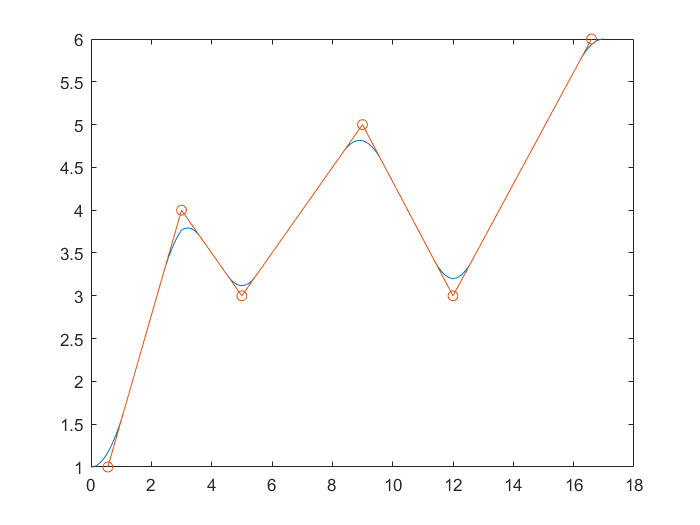

clc, clear
theta = [1, 4, 3, 5, 3, 6]; % 各个中间点的位置
td = [3, 2, 4, 3, 5];       % 每个中间点之间的时间间隔
alpha = [1.1, 1.2, 1.05, 0.9, 1.0, 0.8]; % 过渡阶段的加速度

if length(theta)==length(td)+1 && length(theta) == length(alpha)
%     fprintf("ok")
else
    error("The size of theta should be the same as alpha, and equals the size of td plus 1")
end


num = length(theta);

d_theta = diff(theta);
% 各个点之间，线性部分的斜率，首尾两段后面需要修正
omega = d_theta./td;
% 各个点过渡部分的加速度的符号，首尾两点处暂时用1占位(这里必须是1)，后面单独处理
sng = [1 sign( diff(omega) ) 1];
% 各个点过渡部分的加速度（有符号）
alpha = abs(alpha).*sng;
% 各个点过渡段的时间间隔，首尾两点处暂时用1占位，后面单独处理
t = [1 diff(omega) 1]./alpha;
% 直线部分的时间间隔，首尾两段后面要修正
tl = td - 0.5*t(1:end-1) - 0.5*t(2:end);
% 单独处理第一个点
th1 = theta(1);
th2 = theta(2);
a1 = alpha(1);
a1 = sign(th2-th1) * abs(a1); 
alpha(1) = a1;
td12 = td(1);

t1 = td12 - sqrt( td12^2 - 2*(th2-th1)/a1 ); % 过渡时间
t(1) = t1;
omega12 = (th2-th1)/(td12-0.5*t1);      % 1和2之间线段的斜率(速度)
omega(1) = omega12;
t2 = t(2);
t12 = td12 - t1 - 0.5*t2;       % 1和2之间线性部分的时间长度
tl(1) = t12;
% 单独处理最后一个点
th_n = theta(end);
th_n1 = theta(end-1);
an = sign(th_n1 - th_n)*abs(alpha(end));
alpha(end) = an;
% 最后一个点上的过渡时间长度
tn = td(end) - sqrt( (td(end))^2 + 2*(th_n-th_n1)/an );
t(end) = tn;
omegan1n = (th_n - th_n1)/( td(end) - 0.5*tn );
omega(end) = omegan1n;
tn1n = td(end) - tn - 0.5*t(end-1);
tl(end) = tn1n;

% 求出最终结果
theta0 = theta(1);
thetaf = theta0;
dt = 0.01;
T = 0;
t_all = [];
y_all = [];

for i = 1:num-1
    tf = td(i);
    
    if i == 1
        tb1 = t(i);
    else
        tb1 = t(i)/2;
    end
    if i == num -1
        tb2 = tf - t(i+1);
    else
        tb2 = tf - t(i+1)/2;
    end
%     tb2 = td(i) - tb1 - tl(i);
    a1 = alpha(i);
    a2 = alpha(i+1);
    
    % 中间的直线
    if i == 1
        f2 = @(x) theta(i) + omega(i)*( x - tb1/2 );
    else
        f2 = @(x) theta(i) + omega(i)*x;
    end
    
    % 第一段抛物线
    thetab = f2(tb1);
    p11 = a1/2;
    p12 = omega(i) - a1*tb1;
    p13 = thetab - omega(i)*tb1 + 0.5*a1*tb1^2;
    f1 = @(x) p11*x.^2 + p12*x + p13*ones(size(x));
    
    % 第二段抛物线
    thetac = f2(tb2);
    p21 = a2/2;
    p22 = omega(i) - a2*tb2;
    p23 = thetac - omega(i)*tb2 + 0.5*a2*tb2^2;
    f3 = @(x) p21*x.^2 + p22*x + p23*ones(size(x));
    
    tt1 = 0:dt:tb1;
    tt2 = (tb1+dt):dt:tb2;
    tt3 = (tb2+dt):dt:tf;
    y1 = f1(tt1);
    y2 = f2(tt2);
    y3 = f3(tt3);
    tt = [tt1, tt2, tt3] + T;
    T = T + tf;
    y = [y1, y2, y3];
    
    t_all = [t_all, tt];
    y_all = [y_all, y];

end
td_plt = [0 td];
td_plt = cumsum(td_plt);
td_plt(1) = td_plt(1) + 0.5*t(1);
td_plt(end) = td_plt(end) - 0.5*t(end);
plot(t_all, y_all, td_plt, theta, 'o-')